# Passive RC Filters Study

### by Luca Mandita

This project implements two passive RC filters and studies their behavior. Both the high-pass and low-pass filters use an **18 kOhm resistor** and a **10 nF capacitor**. The project demonstrates how each filter responds to two input sine wave signals with different frequencies (100 Hz and 1 kHz) and visualizes the results through MATLAB plots.

% Mărimi filtru | Filter Values
R = 18000;            % 18k Ohms
C = 10e-9;           % 10 nF

% Calculăm frecvența de tăiere | Cutoff Frequency calculation
fc = 1 / (2 * pi * R * C);
disp(['Cutoff frequency: ', num2str(fc), ' Hz']);

Cutoff frequency: 884.1941 Hz


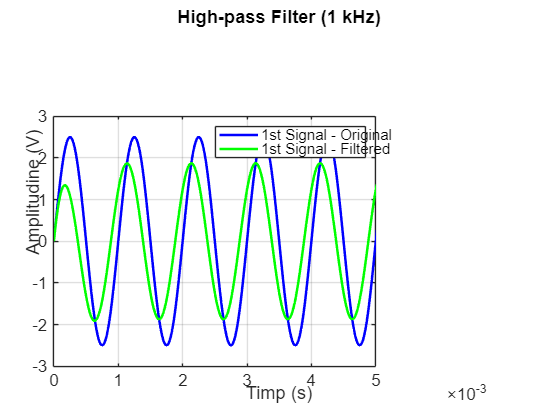


% Generăm semnalul (10 kHz cu 5 Vpp, fără offset) | Signal Generation (1 kHz with 5 Vpp, no DC offset)
fs = 50000;            % Rată eșantionare | Sampling rate
t = 0:1/fs:0.1;       % Vector de timp pentru 0,1 secunde | Time vector for the first 0.1 seconds
f_s1 = 1000;       % Frecvența semnalului | Original signal frequency
f_s2 = 100;
A = 2.5;               % Amplitudinea | Amplitude
x1 = A * sin(2 * pi * f_s1 * t);  % Ecuație semnal | Original signal equation
x2 = A * sin(2 * pi * f_s2 * t);
combinat = x1 + x2;

% Definirea funcției Laplace pentru filtre | Defintion of Laplace transform
s = tf('s');                          % Definim termenul s pentru transformarea Laplace | Define 's' for Laplace transform
H1 = 1 / (R * C * s + 1);              % Transformare Laplace filtru trece-jos
H2 = (R * C * s) / (R * C * s + 1);    % Transformare Laplace filtru trece-sus

% Aplicarea funcției Laplace
y1 = lsim(H1, x1, t);
y2 = lsim(H1, x2, t);
y3 = lsim(H1, combinat, t);

z1 = lsim(H2, x1, t);
z2 = lsim(H2, x2, t);
z3 = lsim(H2, combinat, t);

% Plotare
% High-pass
figure;
plot(t, x1, 'b', 'LineWidth', 1.5);   % Plotarea semnalului de intrare | Original signal plot
hold on;                              
plot(t, z1, 'g', 'LineWidth', 1.5);   % Plotarea semnalului de ieșire | Filtered signal plot
xlabel('Timp (s)');
ylabel('Amplitudine (V)');
title('High-pass Filter (1 kHz)');
legend('1st Signal - Original', '1st Signal - Filtered');
xlim([0, 5e-3]);                    
grid on;                             
hold off;      

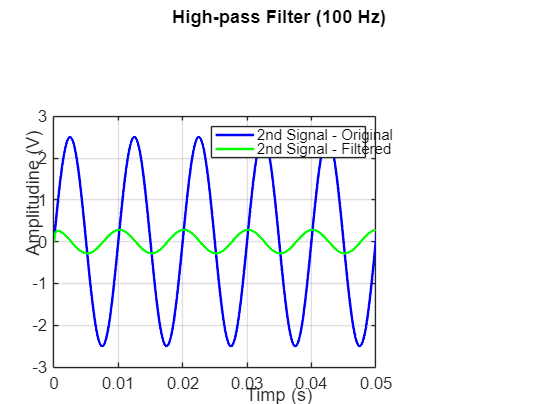


figure;
plot(t, x2, 'b', 'LineWidth', 1.5);   % Plotarea semnalului de intrare | Original signal plot
hold on;                              
plot(t, z2, 'g', 'LineWidth', 1.5);   % Plotarea semnalului de ieșire | Filtered signal plot
xlabel('Timp (s)');
ylabel('Amplitudine (V)');
title('High-pass Filter (100 Hz)');
legend('2nd Signal - Original', '2nd Signal - Filtered');
xlim([0, 5e-2]);                    
grid on;                             
hold off;      

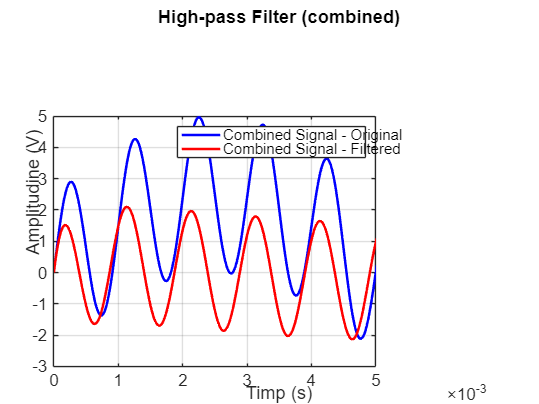


figure;
plot(t, combinat, 'b', 'LineWidth', 1.5);   % Plotarea semnalului de intrare | Original signal plot
hold on;                              
plot(t, z3, 'r', 'LineWidth', 1.5);   % Plotarea semnalului de ieșire | Filtered signal plot
xlabel('Timp (s)');
ylabel('Amplitudine (V)');
title('High-pass Filter (combined)');
legend('Combined Signal - Original', 'Combined Signal - Filtered');
xlim([0, 5e-3]);                    
grid on;                             
hold off;   

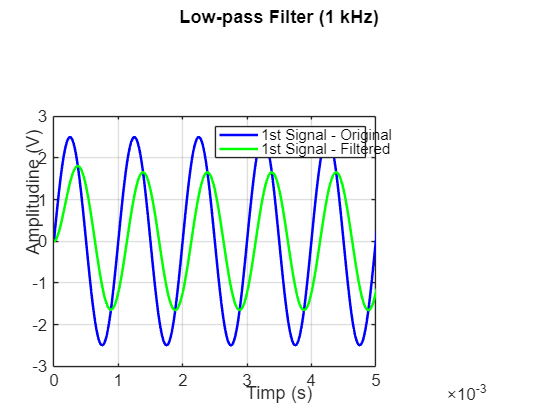


% Low-pass
figure;
plot(t, x1, 'b', 'LineWidth', 1.5);   % Plotarea semnalului de intrare | Original signal plot
hold on;                              
plot(t, y1, 'g', 'LineWidth', 1.5);   % Plotarea semnalului de ieșire | Filtered signal plot
xlabel('Timp (s)');
ylabel('Amplitudine (V)');
title('Low-pass Filter (1 kHz)');
legend('1st Signal - Original', '1st Signal - Filtered');
xlim([0, 5e-3]);                    
grid on;                             
hold off;

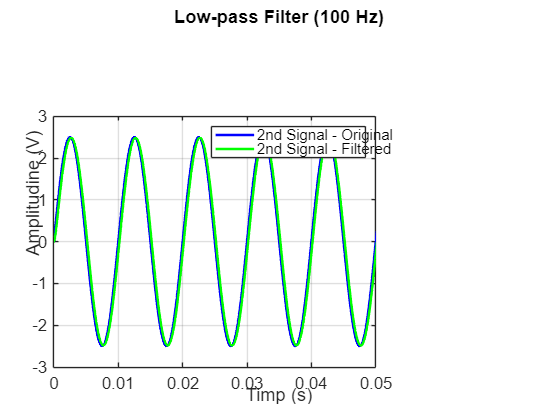


figure;
plot(t, x2, 'b', 'LineWidth', 1.5);   % Plotarea semnalului de intrare | Original signal plot
hold on;                              
plot(t, y2, 'g', 'LineWidth', 1.5);   % Plotarea semnalului de ieșire | Filtered signal plot
xlabel('Timp (s)');
ylabel('Amplitudine (V)');
title('Low-pass Filter (100 Hz)');
legend('2nd Signal - Original', '2nd Signal - Filtered');
xlim([0, 5e-2]);                    
grid on;                             
hold off;

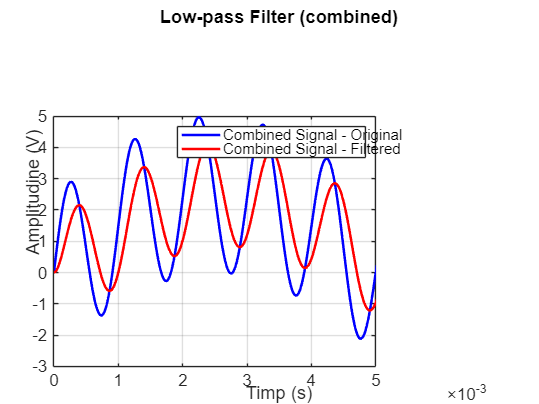


figure;
plot(t, combinat, 'b', 'LineWidth', 1.5);   % Plotarea semnalului de intrare | Original signal plot
hold on;                              
plot(t, y3, 'r', 'LineWidth', 1.5);   % Plotarea semnalului de ieșire | Filtered signal plot
xlabel('Timp (s)');
ylabel('Amplitudine (V)');
title('Low-pass Filter (combined)');
legend('Combined Signal - Original', 'Combined Signal - Filtered');
xlim([0, 5e-3]);                    
grid on;                             
hold off;